# Event-related fields

## **Introduction**

Event-related fields (ERFs) as well as event-related potentials are generated by neuronal activity elicited by and phase-locked to given events. They are often used in cognitive and clinical neurosciene to quantify the brain  activity associated with a given task (Luck 2014, Woodman 2010). The aim of this section is generate event-related fields (ERFs) in response to  the visual input and to do some simple plotting of time course and topographies. 

## **Preparation**

Make sure FieldTrip is installed and the path is set. Then run ft_defaults (only needs running once during each Matlab session). 

ft_defaults

Set the path and the file names of the fif files. We will be using the MaxFiltered data.

data_path = 'C:\YOUR_DATA_FOLDER\';

Load the cleaned planar gradiometer data. 

data=[data_path,'planar_clean.mat']; 
load(data)

## **Filtering and baseline subtraction**

Next 30 Hz lowpass filter will be applied. This is often done when  calculating ERFs. The filtering will be done with padding ('zero-padding') the trial data segments to avoid having ringing artifact. Here 'cfg.padding' is set to 8 seconds, which means 1.75 sec added to both sides of each segment (i.e. 4.5sec+(2*1.75sec)=8sec). Further, a 100 ms pre-stimulus interval (the  baseline) is subtracted from each trial.  

Detrend is set to 'no'. This because slow ERFs can be of cognitive interest.  

cfg = [];
cfg.lpfilter = 'yes';
cfg.lpfreq = 30;      
cfg.padding   = 8;          
cfg.padtype  = 'zero';   
cfg.demean  = 'yes';    
cfg.detrend = 'no'; 
cfg.baselinewindow  = [-0.1 0];
planar_clean_filt = ft_preprocessing(cfg, planar_clean);

the call to "ft_selectdata" took 0 seconds
preprocessing
preprocessing trial 253 from 253

the call to "ft_preprocessing" took 41 seconds


## **Select trials of specific conditions**

The 'attend left' trials and 'attend right' trials had two separate trigger codes (21 and 22, respectively). These trigger codes of each trial are stored in the trialinfo field of the data.  

By using this information we will separate the two types of trials with the ft_selectdata function:    

idx=(find(planar_clean_filt.trialinfo(:,1)==21))';
cfg=[];
cfg.trials=idx;
data_left=ft_selectdata(cfg,planar_clean_filt);

the call to "ft_selectdata" took 0 seconds


clear idx

idx=(find(planar_clean_filt.trialinfo(:,1)==22))';
cfg=[];
cfg.trials=idx;
data_right=ft_selectdata(cfg,planar_clean_filt);

the call to "ft_selectdata" took 0 seconds


The data of the two conditions are now ready for further analysis. 

## **Averaging the trial data**

Key step in ERF calculation is the averaging the amplitude of each  time-point across trials. This is done with the ft_timelockanalysis  function. 

cfg = [];
data_erf_left = ft_timelockanalysis(cfg, data_left);

the input is raw data with 204 channels and 128 trials
the call to "ft_selectdata" took 0 seconds
the call to "ft_timelockanalysis" took 6 seconds


data_erf_right = ft_timelockanalysis(cfg, data_right);

the input is raw data with 204 channels and 125 trials
the call to "ft_selectdata" took 0 seconds
the call to "ft_timelockanalysis" took 4 seconds


The resulting structure does not have 'trial' field anymore, but has the field 'avg' which contains the mean amplitude across trials (channels x time-points). To see the structure write 

data_erf_left

data_erf_left = struct with fields:
      time: [1×4500 double]
     label: {204×1 cell}
      grad: [1×1 struct]
       avg: [204×4500 double]
       var: [204×4500 double]
       dof: [204×4500 double]
    dimord: 'chan_time'
       cfg: [1×1 struct]


## **Plotting event-related fields**

Now we plot the event-related fields over each planar gradiometer. Baseline correction is applied beforehand.

cfg = [];
cfg.layout       = 'neuromag306planar.lay';
cfg.baseline = [-0.1 0]; 
cfg.xlim = [-0.1 0.4]; 
cfg.ylim = [-3e-12 2e-11]; 
ft_multiplotER(cfg, data_erf_left,data_erf_right);

The planar gradiometers are arranged in pairs. Each pair is composed  of two orthogonal planar sensors (ending in XXX2 and XXX3). It is not straightforward to interpret the field maps for planar gradiometers.  Nevertheless, the magnitude of the planar gradiometers is typically the  largest directly above a given current dipole.

**Question 1:** Why is the magnitude of the planar gradient typically strongest directly above a current dipole (hint: explain on the basis of the topographic map of the N100m)

To better interpret the planar gradiometers one can calculate the magnitude of the field for two orthogonal gradiometers combined. We will use the summing option.   

cfg = [];
cfg.method = 'sum';  
data_erf_comb_left = ft_combineplanar(cfg,data_erf_left);

the input is timelock data with 204 channels and 4500 timebins
the input is timelock data with 204 channels and 4500 timebins
constructing single trial from "avg"
the input is raw data with 102 channels and 1 trials


the call to "ft_combineplanar" took 1 seconds


data_erf_comb_right = ft_combineplanar(cfg,data_erf_right);

the input is timelock data with 204 channels and 4500 timebins


the input is timelock data with 204 channels and 4500 timebins
constructing single trial from "avg"
the input is raw data with 102 channels and 1 trials


the call to "ft_combineplanar" took 1 seconds


The resulting structure have 102 combined channels. To inspect write: 

data_erf_comb_left

data_erf_comb_left = struct with fields:
      time: [1×4500 double]
       avg: [102×4500 double]
     label: {102×1 cell}
    dimord: 'chan_time'
       cfg: [1×1 struct]
      grad: [1×1 struct]


To plot the resulting combined averages across trials of the 'attend  left' and 'attend right' conditions, we will use the ft_multiplotER  function. The baseline will be set to the time-window between 100ms and the moving grating onset (time 0).  

the input is timelock data with 102 channels and 4500 timebins
applying baseline correction on avg
the call to "ft_timelockbaseline" took 0 seconds
the input is timelock data with 102 channels and 4500 timebins
applying baseline correction on avg
the call to "ft_timelockbaseline" took 0 seconds
the call to "ft_selectdata" took 0 seconds
reading layout from file neuromag306cmb.lay
the call to "ft_prepare_layout" took 0 seconds


the call to "ft_multiplotER" took 3 seconds


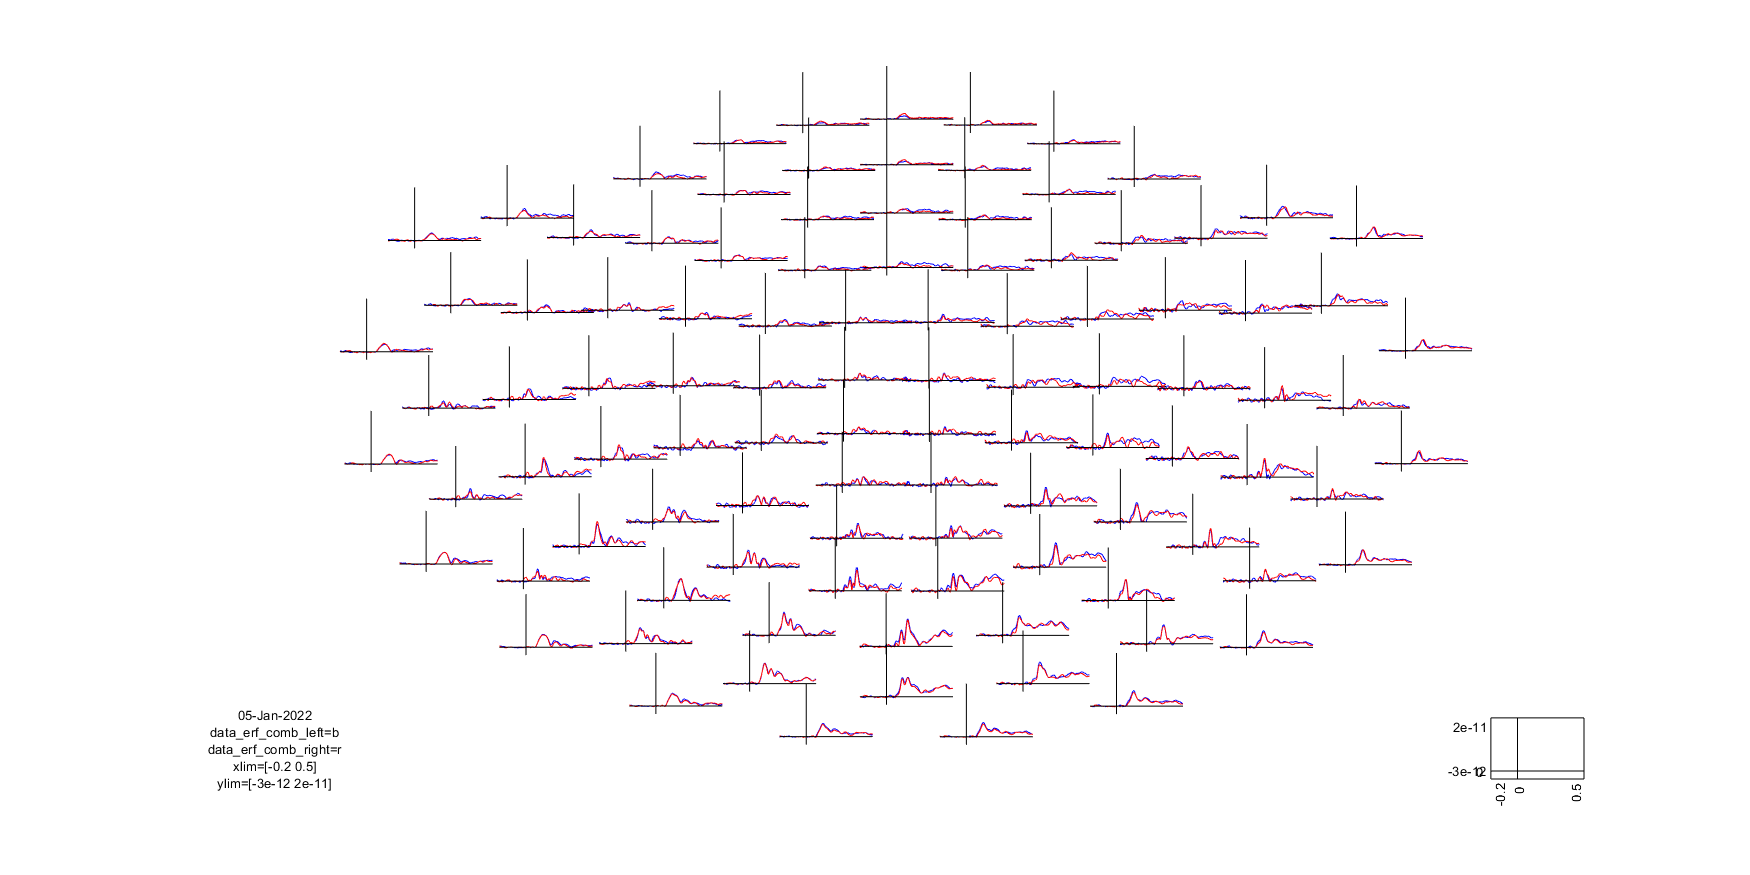

cfg = [];
cfg.layout       = 'neuromag306cmb.lay';
cfg.baseline = [-0.2 0]; 
cfg.xlim = [-0.1 0.4]; 
cfg.ylim = [-3e-12 2e-11]; 
ft_multiplotER(cfg, data_erf_comb_left,data_erf_comb_right);

The plot shows large positive peaks after the moving grating onset over  posterior sensors in both conditions ('attend left' and 'attend right'). 

### **Question 2**

Interpret the time-course of the event-related field: When does the brain first response to the visual input? (change the time axis to  zoom in and show a representative plot)

Next we will examine the topography of the mean amplitude in the time-window at 110 ms after the grating onset with ft_topoplotER

cfg = [];
cfg.layout       = 'neuromag306cmb.lay';
cfg.baseline = [-0.1 0];  
cfg.xlim = [0.110 0.110]; 
cfg.zlim = [0 8e-12];
ft_topoplotER(cfg, data_erf_comb_left);

reading layout from file neuromag306cmb.lay
the call to "ft_prepare_layout" took 0 seconds


the input is timelock data with 102 channels and 4500 timebins
applying baseline correction on avg
the call to "ft_timelockbaseline" took 0 seconds
the call to "ft_selectdata" took 0 seconds


the call to "ft_topoplotER" took 2 seconds


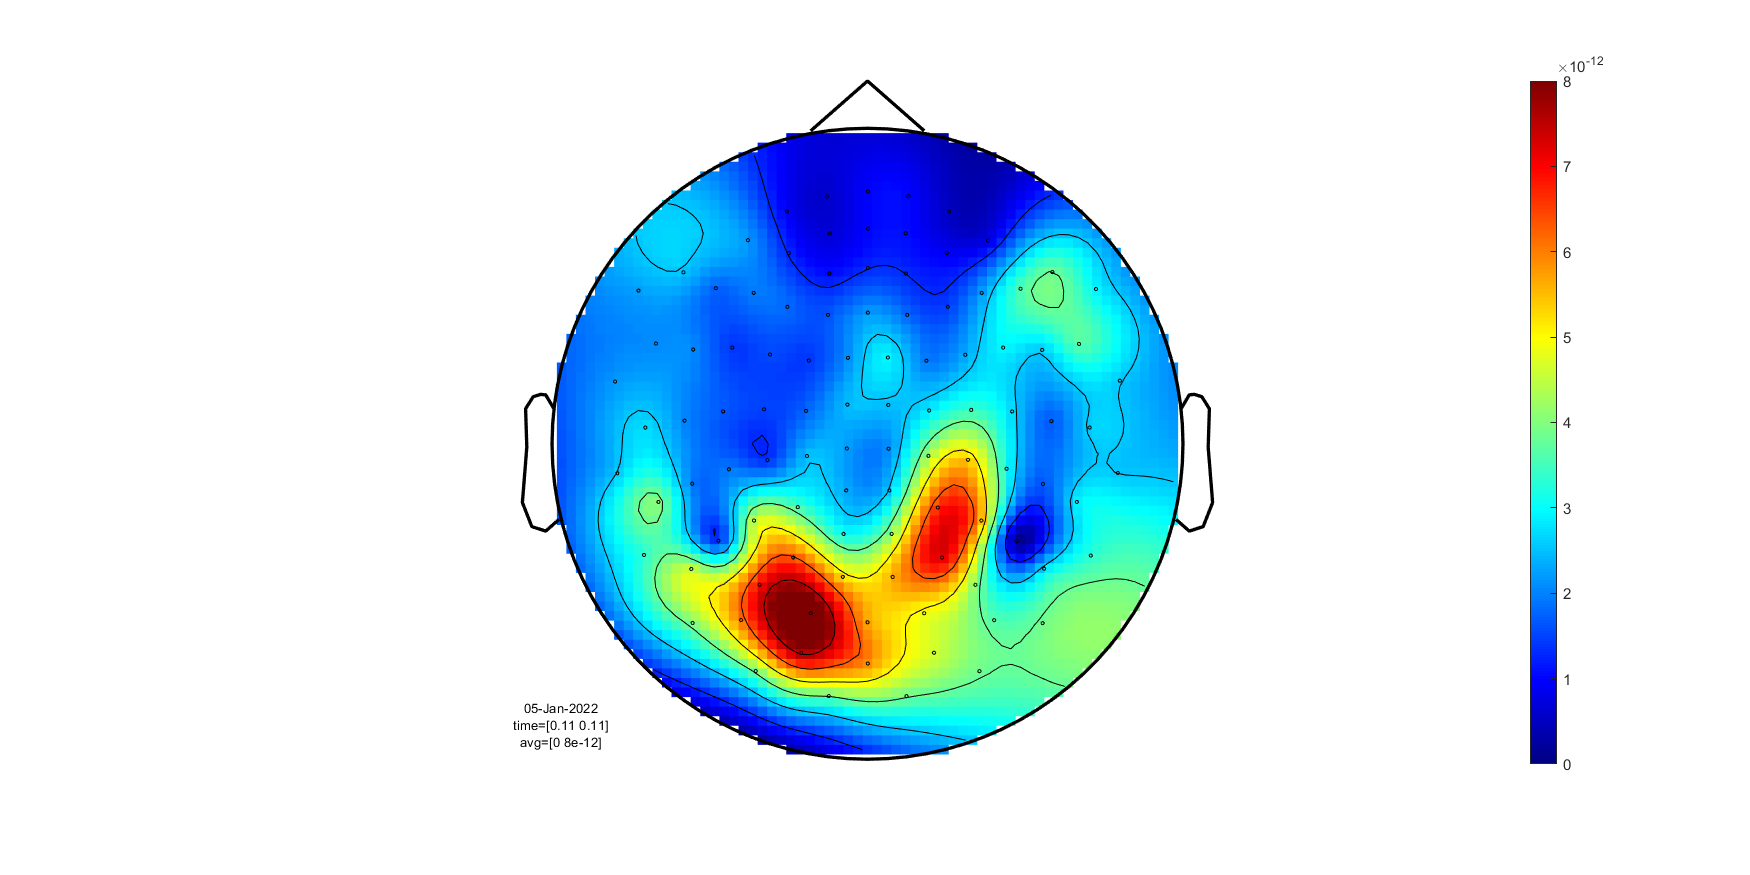

colorbar

### **Question 3**

Interpret the topograpgy of the combined planar gradient in relation to the dipolar map (see Question 1).

### **Question 4**

Plot a sequence of topographic maps for the time-points ranging from 0 to 300 ms in steps of 20 ms.

## Preregistration and publications

**Publication**, example:

"Prior to calculating the event-related fields, the data were lowpass filtered (two-pass butterworth filter) at 30 Hz . After averaging, a 100 ms baseline was subtracted." 

## References

Woodman G.F. (2010) A brief  introduction to the use of event-related potentials in studies of  perception and attention. Atten Percept Psychophys. 72(8):2031-46.

Luck, S.J. (2014) An Introduction to the Event-Related Potential Technique, Second Edition. Bradford Books

(many of the recommendation for calculated event-related potentials also apply to calculating event-related fields)